2.1 Some more on Hilbert Curve

The 3D version of Hilbert Curve

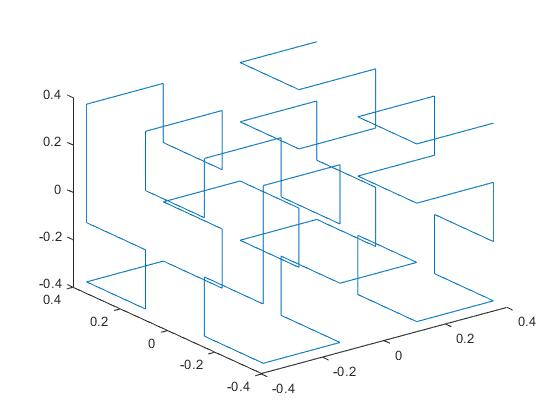

% Plot 3D curve with n = 2
[x, y, z] = hilbert3(2);
figure;
plot3(x, y, z)

Compute the number of turning points

% Number of turning points
nTurning_points = hilbert3_points(2)

nTurning_points = 62

//TODO: Provide a written explanation as to how the 3D code works. What structure is being replicated and how is it moved and rotated?

2.2 Reconstructing the curve

% Three sample sets
set_1 = [ -1 0; -1 1; -1/2 1/2; 0 1; 0 0];
set_2 = [ -1 0; -1 1; -1/2 1/2; 0 1; -1/4 1/4];
set_3 = [ 0 0 1; 0 1 1; -1/2 1/2 1; -1 1 1; -1 0 1; -1 0 0; -1 1 0; -1/2 1/2 0; 0 1 0; 0 0 0];

Solve the Distance Geometry problem using  SVD:

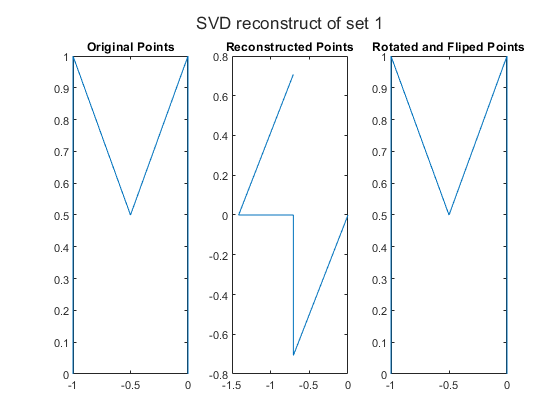

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];


% The distance matrix of set 1
d = distance_matrix(set_1);
X = svd_reconstruct(d);


% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R; 
    X(i, 1) = -X(i, 1); 
end
plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');

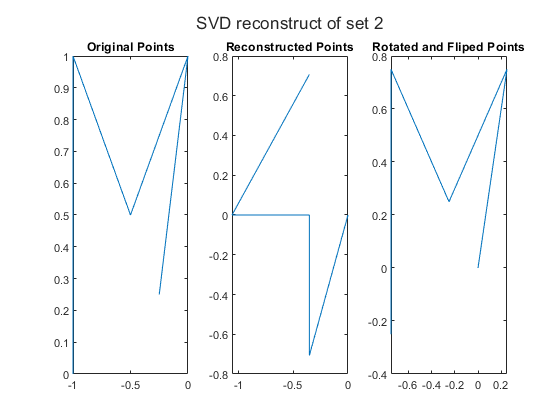


% The distance matrix of set 2
d = distance_matrix(set_2);
X = svd_reconstruct(d);

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R;
    X(i, 1) = -X(i, 1);    
end

plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');

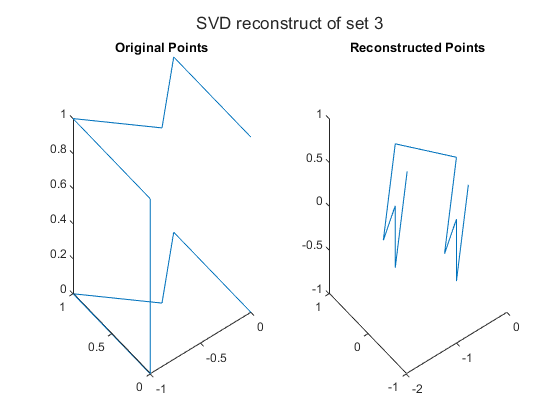


% The distance matrix of set 3
d = distance_matrix(set_3);
X = svd_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "SVD reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

Solve the Distance Geometry problem using  Schur

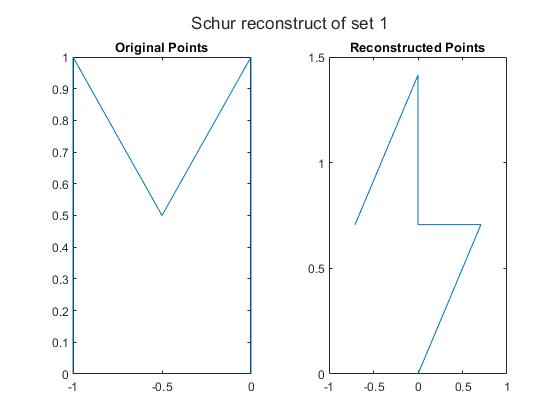

% The distance matrix of set 1
d = distance_matrix(set_1);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

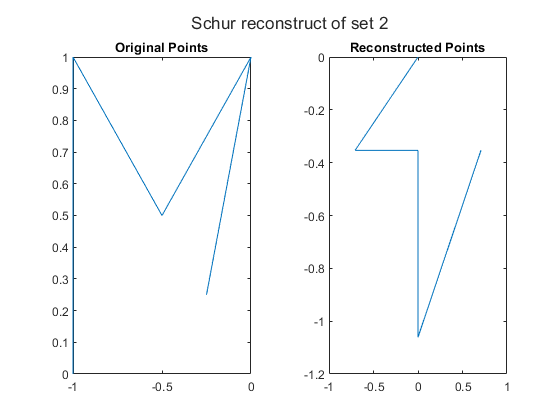


% The distance matrix of set 2
d = distance_matrix(set_2);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

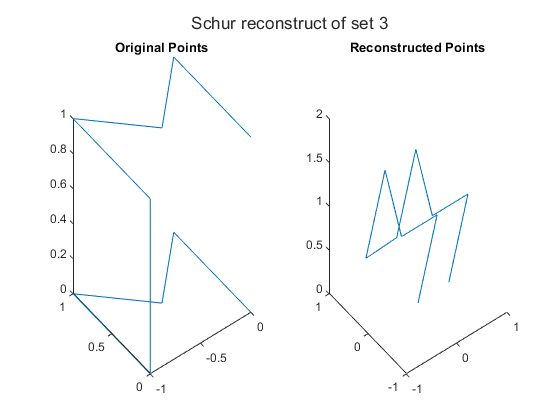


% The distance matrix of set 3
d = distance_matrix(set_3);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

//TODO: Consider rotation

Reconstruct the 2D Hilbert Curve

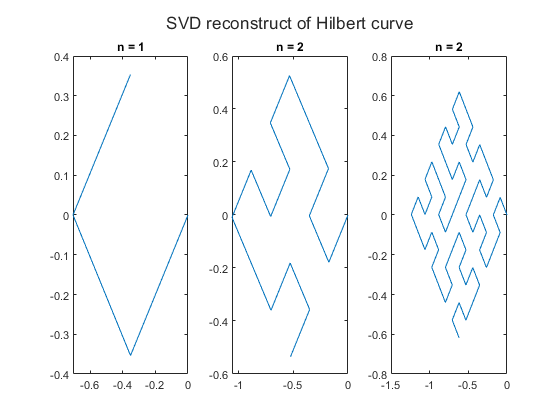


% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of Hilbert curve");

% Hilbert Curve n = 1
d = distance_matrix_hilbert(1, 2);
X = svd_reconstruct(d);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'n = 1');

% Hilbert Curve n = 2
d = distance_matrix_hilbert(2, 2);
X = svd_reconstruct(d);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'n = 2');

% Hilbert Curve n = 3
d = distance_matrix_hilbert(3, 2);
X = svd_reconstruct(d);

ax3 = nexttile;
plot(X(:,1), X(:, 2));
title(ax3,'n = 2');

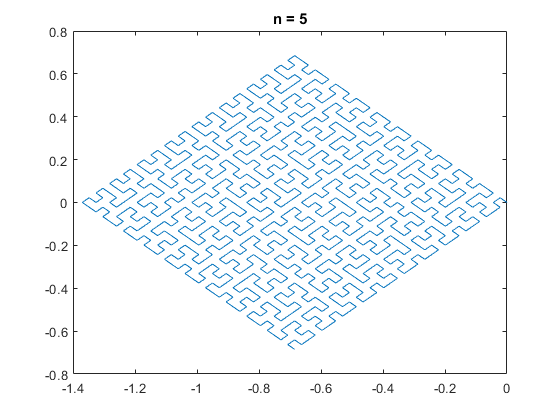



% Hilbert Curve n = 5
figure;
d = distance_matrix_hilbert(5, 2);
X = svd_reconstruct(d);


plot(X(:,1), X(:, 2));
title('n = 5');

Plot singular value of SVD

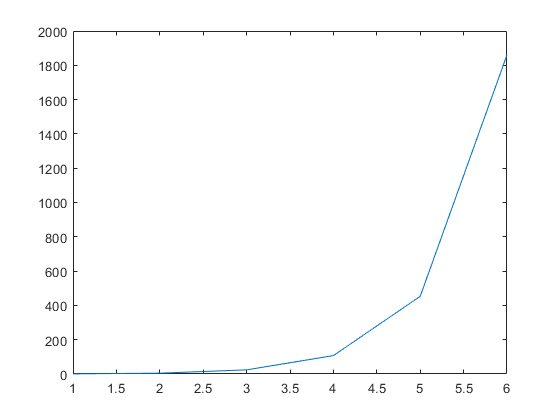

s_values = [];
iteration = 1:6;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 2);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values)

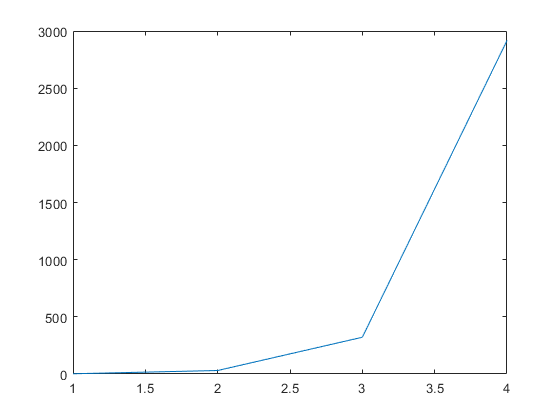


s_values = [];
iteration = 1:4;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 3);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values)